Basic, Time delay, eplison, 2 threshold, time threshold.

Basic model: only one policy (lockdown)

tspan = [0 100];   % days
S0 = 0.7;           % initial susceptible population 
I0 = 0.3;           % initial intected proportion

p0 = [S0; I0];      % vector of ode 
h = 1;
N = (tspan(2)-tspan(1))/h;  % one day

% Euler methods
% Eulerp: the vector[s,i] with threshold policy
% withoutpolicy: vector[s,i] without policy
% betas: the beta changes when threshold policy
[t1,Eulerp,withoutpolicy,betas] = Model0(tspan,p0,N);

The initial population: S:0.70, I:0.30
Time: 1 S0: 0.59 I0: 0.36 beta0: 0.50 S:0.59 I:0.36 beta:0.50 count:0
Time: 2 S0: 0.50 I0: 0.42 beta0: 0.50 S:0.50 I:0.42 beta:0.50 count:0
Time: 3 S0: 0.43 I0: 0.46 beta0: 0.50 S:0.43 I:0.46 beta:0.50 count:1
Time: 4 S0: 0.37 I0: 0.50 beta0: 0.50 S:0.37 I:0.50 beta:0.50 count:2
Time: 5 S0: 0.34 I0: 0.53 beta0: 0.50 S:0.34 I:0.53 beta:0.50 count:3
Time: 6 S0: 0.31 I0: 0.55 beta0: 0.50 S:0.31 I:0.55 beta:0.50 count:4
Time: 7 S0: 0.29 I0: 0.56 beta0: 0.50 S:0.29 I:0.56 beta:0.50 count:5
Time: 8 S0: 0.28 I0: 0.57 beta0: 0.50 S:0.28 I:0.57 beta:0.50 count:6
Time: 9 S0: 0.28 I0: 0.58 beta0: 0.50 S:0.28 I:0.58 beta:0.50 count:7
Time: 10 S0: 0.27 I0: 0.58 beta0: 0.50 S:0.27 I:0.58 beta:0.50 count:8
Time: 11 S0: 0.27 I0: 0.59 beta0: 0.50 S:0.27 I:0.59 beta:0.50 count:9
Time: 12 S0: 0.27 I0: 0.59 beta0: 0.50 S:0.27 I:0.59 beta:0.50 count:10
Time: 13 S0: 0.26 I0: 0.59 beta0: 0.50 S:0.32 I:0.53 beta:0.15 count:11
Time: 14 S0: 0.26 I0: 0.60 beta0: 0.50 S:0.36


subplot(2,2,1);
plot(t1, withoutpolicy(1,:),'r')
hold on;
plot(t1, withoutpolicy(2,:),'b')
hold on;
plot(t1, Eulerp(1,:))
hold on;
plot(t1, Eulerp(2,:))
legend('S_origin','I_origin','S','I');
xlabel('time')
ylabel('population')
title('SIV, when reach threshold, implement policy')

% the phase plane S-I
subplot(2,2,2);
plot(Eulerp(1,:),Eulerp(2,:))
xlabel('S');
ylabel('I');
title('phase plane')

% the beta changes verus time
subplot(2,2,3);
plot(t1, betas)
xlabel('time')
ylabel('beta')
title('The changes of beta')

% different initial state 定义多种不同的初始值
subplot(2,2,4);
p02 = [0.6; 0.4];
[t2,Eulerp2,withoutpolicy2,betas2] = Model(tspan,p02,N);

The initial population: S:0.60, I:0.40
Time: 1 S0: 0.50 I0: 0.46 beta0: 0.50 S:0.50 I:0.46 beta:0.50 count:1
Time: 2 S0: 0.42 I0: 0.51 beta0: 0.50 S:0.42 I:0.51 beta:0.50 count:2
Time: 3 S0: 0.36 I0: 0.54 beta0: 0.50 S:0.36 I:0.54 beta:0.50 count:3
Time: 4 S0: 0.33 I0: 0.57 beta0: 0.50 S:0.33 I:0.57 beta:0.50 count:4
Time: 5 S0: 0.30 I0: 0.59 beta0: 0.50 S:0.30 I:0.59 beta:0.50 count:5
Time: 6 S0: 0.29 I0: 0.60 beta0: 0.50 S:0.29 I:0.60 beta:0.50 count:6
Time: 7 S0: 0.28 I0: 0.60 beta0: 0.50 S:0.28 I:0.60 beta:0.50 count:7
Time: 8 S0: 0.27 I0: 0.61 beta0: 0.50 S:0.27 I:0.61 beta:0.50 count:8
Time: 9 S0: 0.27 I0: 0.61 beta0: 0.50 S:0.27 I:0.61 beta:0.50 count:9
Time: 10 S0: 0.26 I0: 0.61 beta0: 0.50 S:0.26 I:0.61 beta:0.50 count:10
Time: 11 S0: 0.26 I0: 0.61 beta0: 0.50 S:0.32 I:0.55 beta:0.15 count:11
Time: 12 S0: 0.26 I0: 0.61 beta0: 0.50 S:0.36 I:0.49 beta:0.15 count:12
Time: 13 S0: 0.26 I0: 0.61 beta0: 0.50 S:0.39 I:0.45 beta:0.15 count:13
Time: 14 S0: 0.26 I0: 0.61 beta0: 0.50 S:0.

p03 = [0.2; 0.2];
[t3,Eulerp3,withoutpolicy3,betas3] = Model(tspan,p03,N);

The initial population: S:0.20, I:0.20
Time: 1 S0: 0.23 I0: 0.21 beta0: 0.50 S:0.23 I:0.21 beta:0.50 count:0
Time: 2 S0: 0.25 I0: 0.22 beta0: 0.50 S:0.25 I:0.22 beta:0.50 count:0
Time: 3 S0: 0.26 I0: 0.23 beta0: 0.50 S:0.26 I:0.23 beta:0.50 count:0
Time: 4 S0: 0.28 I0: 0.24 beta0: 0.50 S:0.28 I:0.24 beta:0.50 count:0
Time: 5 S0: 0.28 I0: 0.26 beta0: 0.50 S:0.28 I:0.26 beta:0.50 count:0
Time: 6 S0: 0.29 I0: 0.27 beta0: 0.50 S:0.29 I:0.27 beta:0.50 count:0
Time: 7 S0: 0.29 I0: 0.29 beta0: 0.50 S:0.29 I:0.29 beta:0.50 count:0
Time: 8 S0: 0.30 I0: 0.31 beta0: 0.50 S:0.30 I:0.31 beta:0.50 count:0
Time: 9 S0: 0.30 I0: 0.33 beta0: 0.50 S:0.30 I:0.33 beta:0.50 count:0
Time: 10 S0: 0.30 I0: 0.34 beta0: 0.50 S:0.30 I:0.34 beta:0.50 count:0
Time: 11 S0: 0.29 I0: 0.36 beta0: 0.50 S:0.29 I:0.36 beta:0.50 count:0
Time: 12 S0: 0.29 I0: 0.38 beta0: 0.50 S:0.29 I:0.38 beta:0.50 count:0
Time: 13 S0: 0.29 I0: 0.40 beta0: 0.50 S:0.29 I:0.40 beta:0.50 count:0
Time: 14 S0: 0.29 I0: 0.41 beta0: 0.50 S:0.29 I

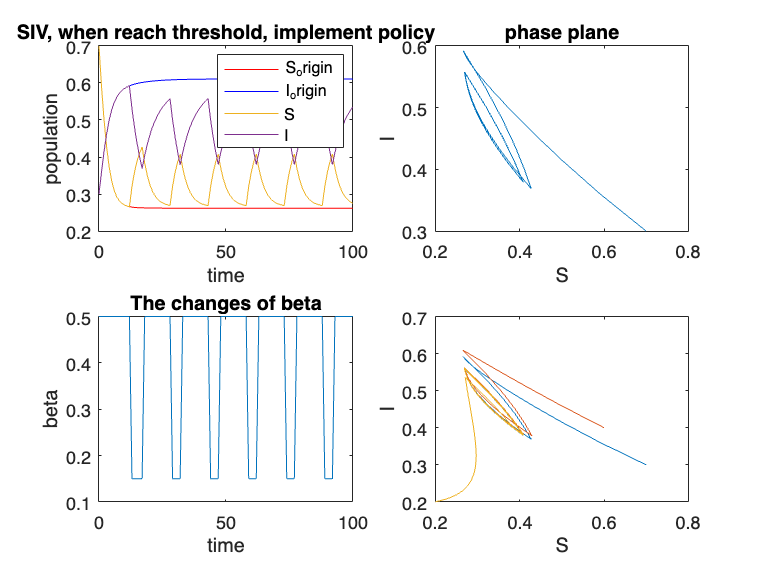

plot(Eulerp(1,:),Eulerp(2,:))
hold on;
plot(Eulerp2(1,:),Eulerp2(2,:))
hold on;
plot(Eulerp3(1,:),Eulerp3(2,:))
xlabel('S')
ylabel('I')

function: Model

% This combine SIV ode function and Euler together 
% change the beta 


function [t,r,withoutpolicy,betachange] = Model0(tspan,yI,N)

% S:x(1) I:x(2) 
beta0 = 0.5;         % infection rate when there is no policy

Ic = 0.4;           % the threshold of infectious people
f = 1;            % intensity of measurements


% Forward Euler method
tI = tspan(1);
tF = tspan(2);
h = (tF - tI)/N;

d = numel(yI);  % return the size of yI
y = zeros(d, N+1);
y(:,1) = yI;  % 2*1 matrix y(1,1)=S, y(2,1)=I

% To plot the situation when there is no policy
without(:,1) = yI;
withoutpolicy(:,1) = yI;

t=linspace(tI,tF,N+1)'; 

r(:,1) = yI;      % return the ode solution

t = 0;
betachange = beta0;

count =0;  

fprintf('The initial population: S:%.2f, I:%.2f\n', y(1,1),y(2,1));

for k = 1:N   %time h:day
    % eplison should be 0-1
%       eplison = 0.5;  % 数字越大，持续封锁措施时间越长
%      eplison = randomwalk(k);    
%        eplison = sigmoid(0.05*k);  % have oscillation

    if y(2,1) < Ic
        beta = 0.5;
        count = 0;  % If the infected people lower than threshold, the government will not implement the policy.
    elseif y(2,1) >=Ic && count <10
        beta = 0.5;
        count = count + 1;

    elseif y(2,1) >=Ic && count >=10
%          eplison = sigmoid(count-10);
         eplison = 0.7;
%         eplison = randomwalk(count -10);  % 更合理
        beta = (1-f*eplison)*beta0; 
        count = count + 1;  % 表示执行计划开始的时间 eplision越大 beta越小
    end

    without = without(:,1)+odefunction(without(:,1),beta0);
    y(:,1) = y(:,1)+odefunction(y(:,1),beta);

    fprintf('Time: %d S0: %.2f I0: %.2f beta0: %.2f S:%.2f I:%.2f beta:%.2f count:%d\n', ...
        k,without(1,1),without(2,1),beta0,y(1,1),y(2,1),beta,count);
    
    yv = [y(1,1);y(2,1)];

    withoutpolicy = [withoutpolicy without];
    r = [r yv];
    t = [t k];
    betachange = [betachange beta];
%     fprintf('beta: %f count: %d\n', beta,count);

end

fprintf('==================================================\n');
end